# Load and Format Data for Abalone Targets

`[AbaloneInputs, AbaloneTargets] = LoadAbalone(Preview)` loads the abalone dataset packaged with MATLAB and prepares and outputs the Abalone`Inputs` and Abalone`Targets` tables. The optional argument `Preview `is a logical that enables the user to choose whether or not to preview data. The original dataset does not include row or column headers.

In the first section, we load Abalone_dataset.mat into two variables, abaloneInputs and abaloneTargets. These variables appear in our workspace.

 

We notice that abalone`Inputs` is an 8 x 4177 double, and abalone`Targets` is a 1 x 4177 double. From the [doc](https://www.mathworks.com/help/matlab/ref/doc.html?searchHighlight=doc&s_tid=srchtitle_support_results_1_doc) function, we learn the dataset is representative of 8 different abalone shell attributes for 4177 shells.  Each row in the `abaloneInputs` variable represents the shell (the independent variable), and each column corresponds to a shell. Similarly, in `abaloneOutputs`, we see that each row represents an attribute. We use `array2table` to convert the two matrices loaded into the workspace into a table with labeled columns and rows. 

Learn more about tables in the self-paced course, [Tables](https://matlabacademy.mathworks.com/details/tables/otmltab). With our data now in a table, we can add row names and column names to both tables. Tables are powerful in MATLAB. Consider exploring the [Organizing Tabular Data in MATLAB](https://matlabacademy.mathworks.com/details/organize-tabular-data-in-matlab/lpmlotd) learning path.

We name the tables `AbaloneInputs`, and `AbaloneTargets`. If you double-click on the `AbaloneInputs` in the workspace to view the table, a new window will open. In this window, you will see the dataset along with summary statistics for each column. 

 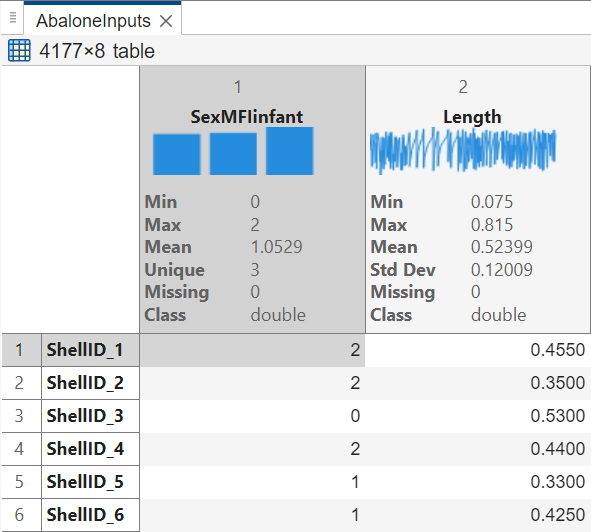

If you would like to preview the first 10 rows of the data, you can check the Preview data box or set `Preview == 1` in your function call. Here is an example of what you will see with the dataset preview:

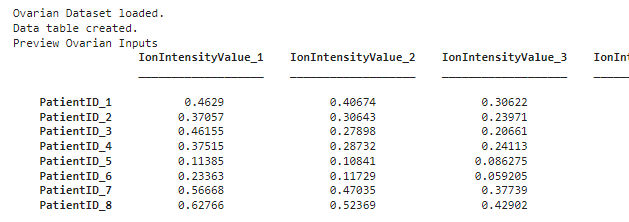

function [AbaloneInputs, AbaloneTargets] = LoadAbalone(Preview,Help)
arguments
    Preview (1,1) logical = false
    Help (1,1) logical = false
end
load abalone_dataset.mat abaloneInputs abaloneTargets % Load two variables: abaloneTargets and abaloneInputs
disp("Abalone Dataset loaded.")

## Create Data Tables

AbaloneInputs = array2table(abaloneInputs'); % Convert and transpose abaloneInputs matrix to a table
AbaloneTargets = array2table(abaloneTargets'); % Convert and transpose abaloneTargets matrix to a table

AbaloneInputs.Properties.RowNames = strcat("ShellID_",string(1:height(AbaloneInputs))); % Label the rows as 'Shell ID: 1', 'Shell ID: 2', etc.
AbaloneInputs.Properties.VariableNames = ["SexMFIinfant" "Length" "Diameter" "Height" "Wholeweight" "Shuckedweight" "Visceraweight" "Shellweight"]; % Label the columns as 'SexMFIinfant', 'Length', etc.

AbaloneTargets.Properties.RowNames = strcat("ShellID_",string(1:height(AbaloneTargets))); % Label the rows as 'Shell ID_1', 'Shell ID_2', etc.
AbaloneTargets.Properties.VariableNames = strcat("Age_",string(1:width(AbaloneTargets))); % Label the columns as 'Age'.
disp("Data table created.")

## Preview Data Tables

If you would like to preview the data tables, select the Preview checkbox.

if Preview == true % Display the first ten lines of each table if preview is selected
    disp("Preview Abalone Inputs")
    head(AbaloneInputs) % Display first 10 lines of AbaloneInputs
    disp("Preview Abalone Targets")
    head(AbaloneTargets) % Display first 10 lines of AbaloneTargets
end

## Display Help for Data

Open the [doc](https://www.mathworks.com/help/releases/R2025a/matlab/ref/doc.html?searchHighlight=doc&s_tid=doc_srchtitle) documentation to learn about the dataset.

if Help == true % Display the help section if Help is selected
    doc abalone_dataset
end

end